# Демодуляция. Часть 3.

# Double Sideband Suppressed Carrier 

# (AM-DSB-SC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Когерентная демодуляция с помощью схемы Костаса

Наиболее популярный метод приема АМ-сигнала с подавленной несущей заключается в использовании схемы Костаса (Costas Loop). Схема приемного устройства представлена ниже:

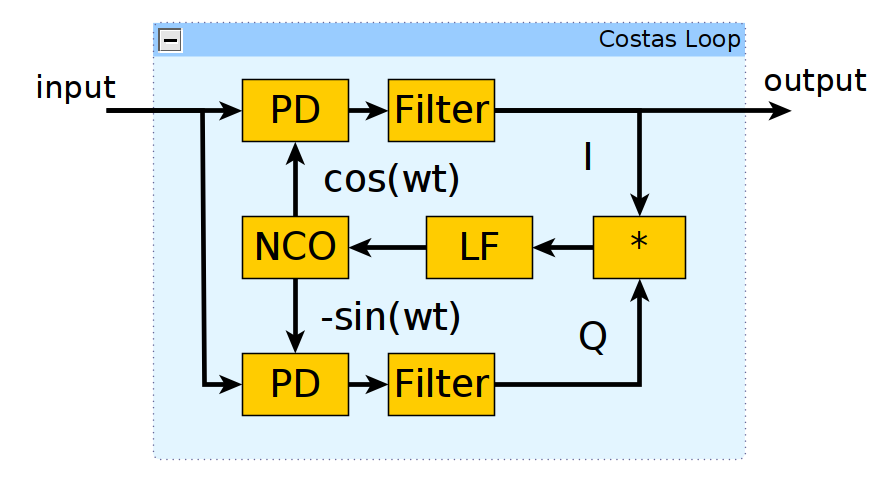

Принцип работы схемы Костаса совпадает с обычной PLL. Сигнал поступает на фазовый детектор PD, где вычисляется расстройка по фазе между несущей и управляемым генератором (NCO). Петлевой фильтр задает динамику системы и убирает лишние шумы.

В отличие от обычной PLL в схеме Костаса используется два фазовых детектора, после которых стоят фильтры нижних частот. Также NCO формирует сразу два гармонических сигнала: $\cos \left(\Phi_г \right)$ и $-\sin \left(\Phi_г \right)$. Разберемся как данная схема работает.

Пусть принятый АМ-сигнал имеет вид:

$s_{\mathrm{am}} \left(t\right)=m\left(t\right)\cdot \cos \left(2\pi f_c t\right)$,

где $m\left(t\right)$ - информационное сообщение, $f_c$ - частота несущей. Как было сказано в DSB SC Receiver Part 2 изменение знака информационного сообщения $m\left(t\right)$ будет приводить к появлению качков фазы несущей на 180 градусов, что негативно скажется на качестве синхронизации. Чтобы избавится от скачков фазы, необходимо сделать так, чтобы амплитуда несущей не изменяла знак.

В схеме Костаса есть две ветви: синфазная (I) и квадратурная (Q). В синфазной ветви АМ-сигнал смешивается с $\cos \left(\Phi_г \right)$, где $\Phi_г \left(t_0 \right)=\Phi_с \left(t_0 \right)-\Delta$, $\Phi_с \left(t_0 \right)$ - фаза несущей, $\Delta$ - расстройка по фазе. В результате получаем:

 $s_I \left(t\right)=m\left(t\right)\cdot \mathrm{cos}\left(\Phi_с \left(t_0 \right)\right)\cdot \mathrm{cos}\left(\Phi_г \left(t_0 \right)\right)=m\left(t\right)\cdot 0\ldotp 5\cdot \mathrm{cos}\left(\Delta \right)+m\left(t\right)\cdot 0\ldotp 5\cdot \mathrm{cos}\left(2\Phi_c \left(t_0 \right)-\Delta \right)$.

Квадратурная ветвь умножается на $-\sin \left(\Phi_г \right)$. Выход фазового детектора для этой ветви равен:

$s_Q \left(t\right)=m\left(t\right)\cdot \mathrm{cos}\left(\Phi_с \left(t_0 \right)\right)\cdot -\mathrm{sin}\left(\Phi_с \left(t_0 \right)-\Delta \right)=m\left(t\right)\cdot 0\ldotp 5\cdot \mathrm{sin}\left(\Delta \right)-m\left(t\right)\cdot 0\ldotp 5\cdot \mathrm{sin}\left(2\Phi_c \left(t_0 \right)-\Delta \right)$.

После фильтрации сигналы на удвоенной частоте исчезнут, и мы получим:


$$s_{\mathrm{Filtered}\;I} \left(t\right)=m\left(t\right)\cdot 0\ldotp 5\cdot \cos \left(\Delta \right),\;\;\;\;s_{\mathrm{Filtered}\;Q} \left(t\right)=m\left(t\right)\cdot 0\ldotp 5\cdot \sin \left(\Delta \right)\ldotp$$


Далее сигналы синфазной и квадратурной ветвей перемножаются, и результат подается на вход петлевого фильтра:


$$s_{\mathrm{LF}} \left(t\right)=m^2 \left(t\right)\cdot 0\ldotp 25\cdot \cos \left(\Delta \right)\cdot \sin \left(\Delta \right)=m^2 \left(t\right)\cdot 0\ldotp 125\cdot \sin \left(2\Delta \right)\ldotp$$


Таким образом, вход петлевого фильтра не изменяет знак при изменении знака информационного сообщения. В результате преобразований мы опять получаем возведение информационного сообщения в квадрат. Если приемник находится в режиме синхронизации, то есть, когда расстройка по фазе мала, то $\sin \left(2\Delta \right)\approx 2\Delta$. Таким образом, вход петлевого фильтра пропорционален расстройке по фазе. Также при синхронизации фильтрованный сигнал синфазной ветви будет иметь вид:

$s_{\mathrm{Filtered}\;I} \left(t\right)=m\left(t\right)\cdot 0\ldotp 5\cdot \cos \left(\Delta \right)\approx$$m\left(t\right)\cdot 0\ldotp 5\cdot 1$,

где учтено, что при малых значениях $\Delta$, $\cos \left(\Delta \right)\approx 1$. Значит, при синхронизации синфазная ветвь будет содержать восстановленное информационное сообщение.

Для реализации всех рассмотренных выше преобразований был создан Matlab System Object, описание которого находится в файле CostasAmSignalPLL.m. Ниже представлен скрипт, выполняющий когерентный прием сигнала с амплитудной модуляцией с подавленной несущей. С помощью переменной FreqOffset можно изменять расстройку между частотой несущей и начальной частотой управляемого генератора.

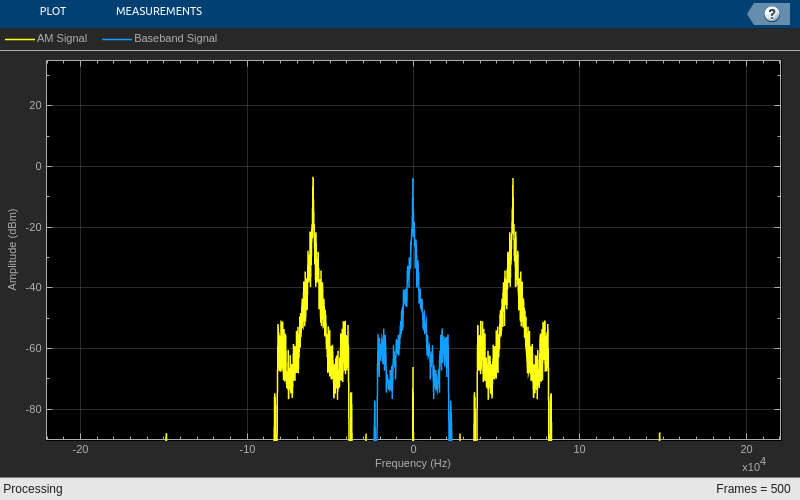

clc; clear; close all;
addpath('matlab/DSB_SC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_SC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
% параметры фапч зависят от амплитуды входного сигнала
% его амплитуда меняется поэтому берем среднее значение, равное 0.27
CostasPLL = CostasAmSignalPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset, ...
    'SignalAmp', 0.0012 ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Baseband Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % восстанавливаем несущую
    [BasebandSignal, Offset] = CostasPLL(AmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal BasebandSignal]);
kd = 1; 
    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым обозначен спектр принимаемого АМ-сигнала. После схемы Костаса имеем восстановленное информационное сообщение (синий).

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить искажения при восстановлении информационного сообщения. Как и для случая возвдения сигнала в квадрат, для не слишком больших расстроек по частоте сообщение восстанавливается без икажений.

### 2. Когерентная демодуляция с помощью схемы Костаса при квадратурном приеме

Рассмотрим особенности реализации схемы Костаса в случае квадратурного приема. Во много схема совпадает со случаем действительного сигнала. Однако есть и отличия. Теперь NCO также формирует комплексный сигнал. После фазового детектора отсутствует фильтр, и есть блок разделяющий комплексный сигнал на синфазную и квадратурную ветви. Схема приемного устройства представлена ниже:

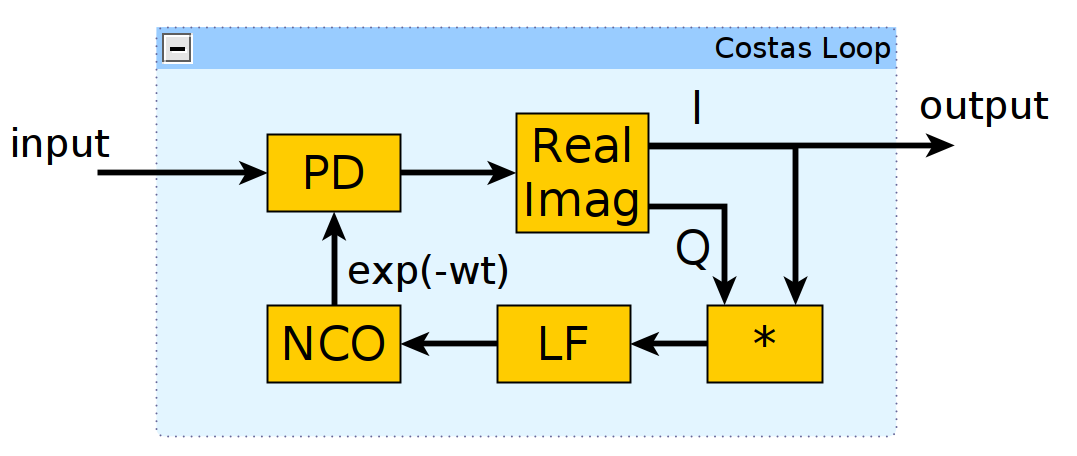

Рассмотрим принцип работы схемы Костаса для квадратурного приема. Сигнал теперь комплексный с односторонним спектром и представлен в виде:

 $s_{\mathrm{am}} \left(t\right)=m\left(t\right)\cdot e^{j\cdot 2\pi f_c t}$,

где $m\left(t\right)$ - информационное сообщение, $f_c$ - частота несущей. После умножения на комплексную экспоненту с выхода NCO получим:

$s_{\mathrm{PD}} \left(t\right)=m\left(t\right)\cdot e^{j\cdot \Delta }$.

где $\Delta$ - расстройка по фазе между несущей и управляемым генератором. Далее формируются сигналы синфазного и квадратурного каналов, которые совпадают с действительной и мнимой частью выхода фвзового детектора. После перемножения каналов получаем, что сигнал на входе петлевого фильтра равен:

$s_{\mathrm{LF}} \left(t\right)=m^2 \left(t\right)\cdot \;\mathrm{Re}\left\lbrace e^{j\cdot \Delta } \right\rbrace \cdot \mathrm{Im}\left\lbrace e^{j\cdot \Delta } \right\rbrace =m^2 \left(t\right)\cdot \cos \left(\Delta \right)\cdot \sin \left(\Delta \right)=m^2 \left(t\right)\cdot 0\ldotp 5\cdot \sin \left(2\Delta \right)$.

То есть сигнал для петлевого фильтра с точностью до масштабирующего множителя совпадает с сигналом для ранее рассмотренного действительного случая. При синхронизации в синфазной ветви появится восстановленное информационное сообщение.

Для реализации всех рассмотренных выше преобразований был создан Matlab System Object, описание которого находится в файле CostasAmSignalComplexPLL.m. Ниже представлен скрипт, выполняющий когерентный прием сигнала с амплитудной модуляцией с подавленной несущей. С помощью переменной FreqOffset можно изменять расстройку между частотой несущей и начальной частотой управляемого генератора.

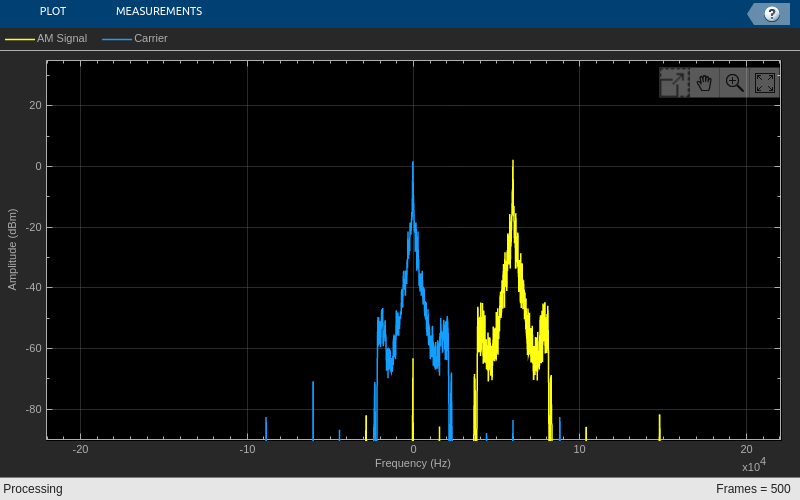

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_SC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
CostasPLL = CostasAmComplexPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset, ...
    'SignalAmp', 0.0012 ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Baseband Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % восстанавливаем несущую
    [BasebandSignal, Offset] = CostasPLL(AmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal BasebandSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым обозначен спектр принимаемого АМ-сигнала. После схемы Костаса получется восстановленное информационное сообщение (синий).

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить искажения при восстановлении сигнала. Как и для случая возвдения сигнала в квадрат, для не слишком больших расстроек по частоте информационное сообщение восстанавливается без икажений.

В файле *DSB_SC_Receiver_Part_3.slx* представлена Simulink модель когерентного демодулятора, который ранее был реализован ввиде скрипта. В модели присутствует обычная PLL и PLL, выполненная по схеме Костаса. С помощью переключателя можно выбрать, какую из них использовать и сравнить качество восстановления аудиосообщения.

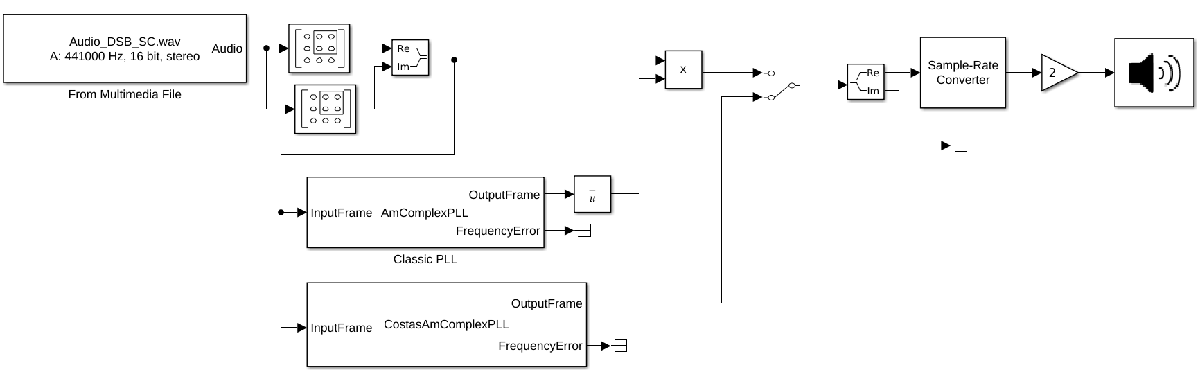

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR

- M. Rice Digital Communications. A Discrete Time Approach

- B. Sclar Digital Communications. Fundamentals and Applications